# User Input

Fs = 1e5; % Hz (Sampling Rate)

Rm = 1500; % MOhms (Membrane Resistance)
Rs = 47; % MOhms (Series Resistance)
Cm = 60; % pF (Membrane Capacitance)

## Convert Variables

Rm = Rm * 1e6;   % Convert Rm (MOhms) to (Ohms)
Rs = Rs * 1e6;   % Convert Rs (MOhms) to (Ohms)
Cm = Cm * 1e-12; % Convert Cm (pF) to (F)

%
%   o---Rs--|---|---o
%           |   |
%   Vin     Rm  Cm  Vout
%           |   |
%   o-------|---|---o
% 

## Laplace (Continuous) Solution

% Access Resistance and Cell filter input voltage in voltage clamp mode
% by the following transfer function
% H(s) = 1 / ((Ra * C)s + (1 + Ra/Rm)) [Laplace Domain]
% Laplace (Analog) Solution
b_laplace = [1];
a_laplace = [Rs * Cm, Rs/Rm + 1];

## Z Transform (Discrete) Approximation

% Laplace Domain transfer function is converted to
% Ha(s) = (1/(Ra*C)) / (s + (1+Ra/Rm)*(1/(Rs*C)))
% this is of the form
% Ha(s) = c / (s - lambda)
% this converts to
% H(z) = Tcz/(z - e^(lambda*T)) [Z Domain]
% where T = sampling period (1/Fs)
T = (1/Fs); % s (Sampling Period)
c = 1/(Rs * Cm);
lambda = -(1 + Rs/Rm)*(1/(Rs * Cm));
b_z = [T * c, 0];
a_z = [1, -exp(lambda * T)];

## Plot Laplace and Z transform Bode Plots

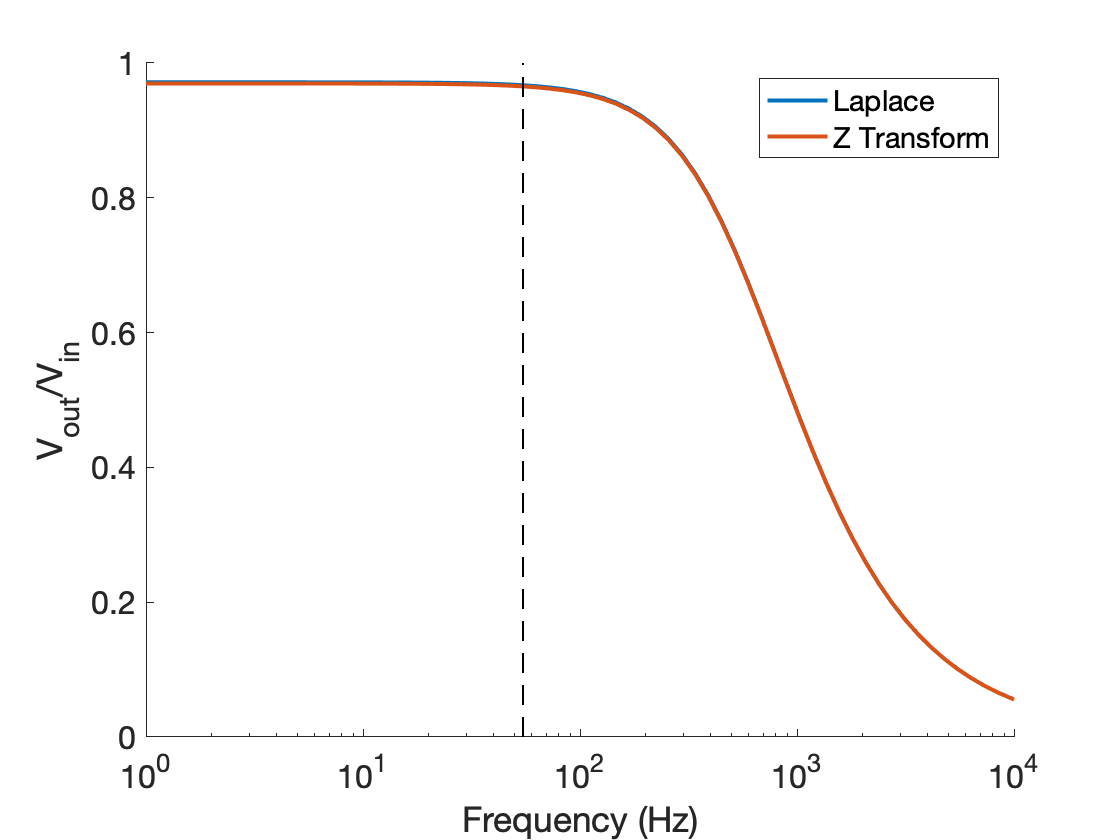

w = logspace(-1, 5, 100); % radians / second
sys_continuous = tf(b_laplace, a_laplace);
[mag_c,phase_c,wout_c] = bode(sys_continuous, w);

sys_discrete = tf(b_z, a_z, T);
[mag_d,phase_d,wout_d] = bode(sys_discrete, w);

Fc = sqrt(Rm^2-2*Rm*Rs-Rs^2)/(2*pi*Cm*Rm*Rs); % From Bill Connelly Blog

figure; hold on;
plot(wout_d / 2*pi, squeeze(mag_d), 'LineWidth', 2);
plot(wout_c / 2*pi, squeeze(mag_c), 'LineWidth', 2);

plot([Fc, Fc], [0, 1], 'k--', 'LineWidth', 1);
set(gca, 'XScale', 'log');
legend({'Laplace', 'Z Transform'});
xlim([1e0, 1e4]);
xlabel('Frequency (Hz)');
ylabel('V_{out}/V_{in}');
set(gca, 'FontSize', 16);

## Simulate Filtered Command

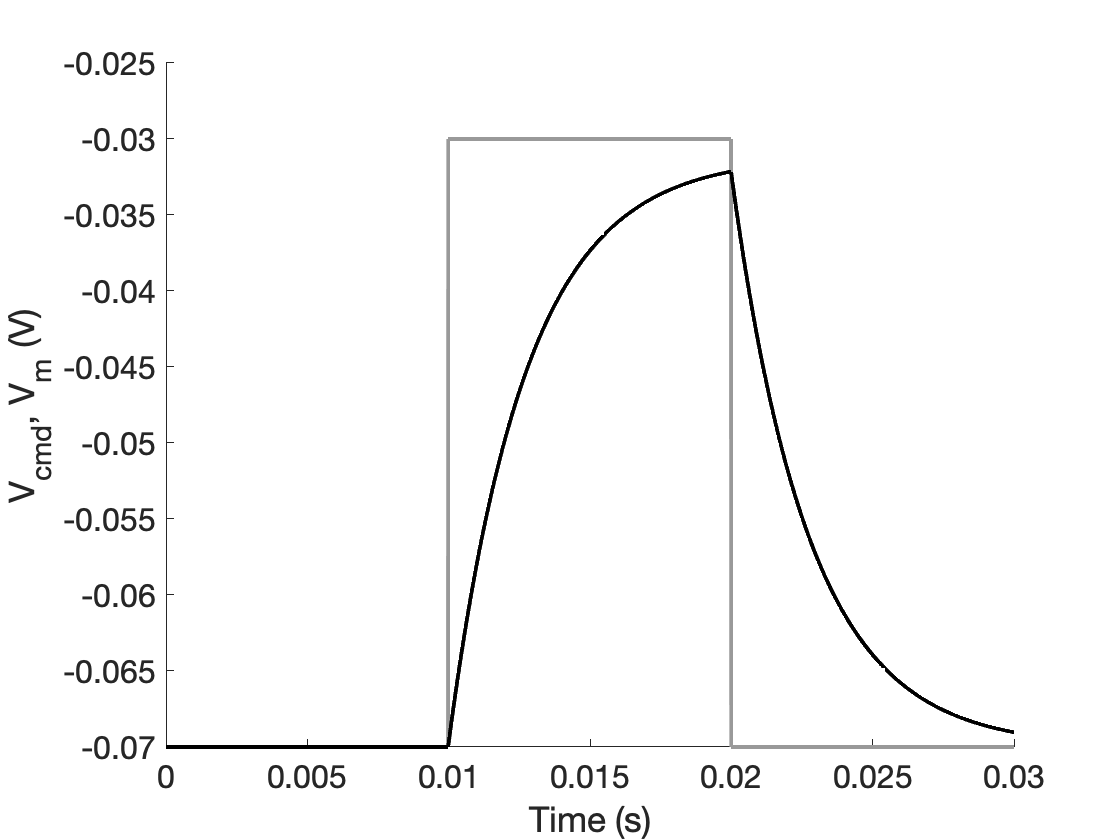

V_holding = -70; % mV
V_cmd_amplitude = 40; % mV
V_cmd_width = 10; % ms
V_cmd_delay = 10; % ms

V_cmd_width_samp = round((V_cmd_width/1000) / T);       
V_cmd_delay_samp = round((V_cmd_delay / 1000) / T);

V_cmd = zeros(1,3000) + V_holding/1000;s
V_cmd(V_cmd_delay_samp:(V_cmd_delay_samp + V_cmd_width_samp)) = (V_holding + V_cmd_amplitude) / 1000;
time = 0:T:((length(V_cmd)-1)*T);

filtered = filter(b_z, a_z, V_cmd-V_cmd(1))+V_cmd(1); %shift to zero, then back to avoid initial transients
figure; hold on;
plot(time, V_cmd, 'k', 'LineWidth', 2, 'Color', [.6, .6, .6, 1]); 
plot(time, filtered, 'LineWidth', 2, 'Color', [0, 0, 0, 1]);
xlabel('Time (s)');
ylabel('V_{cmd}, V_m (V)');
set(gca, 'FontSize', 16);